# Práctica 2: Análisis de métodos de control de complejidad

## Abstract

Estudio estadístico que analiza el comportamiento de  los métodos de selección de modelos. Comparando k-CV, Bootstrap, y los métodos de penalización AIC y AICC. Utiliza la familia de funciones polinomiales como funciones aproximadoras.

## Conjunto de datos

## Generación de datos teóricos (Población)

Para generar la función teórica se ha generado una muestra de 1000 ejemplos. Con ella calcularemos el ruido que usaremos para generar las muestras para realizar los experimentos.

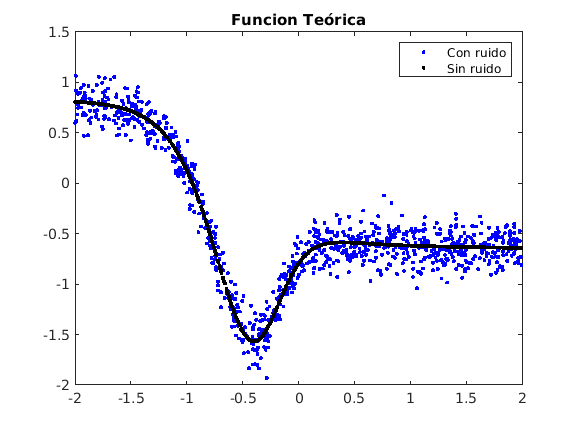

clear all
close all
clc
warning('off','all');

num_points = 1000;

%Definimos x e y.
x=4*(rand(1,num_points)-0.5);
yok=1.8 *tanh(3.2 * x + 0.8)- 2.5 * tanh(2.1 * x + 1.2)-0.2 * tanh(0.1 * x-0.5); 

%Definimos ruido y se lo añadimos a nuestra y.
RUIDO=0.2 * std(yok);
yruido=RUIDO * randn(size(yok));
y=yok+yruido;

plot(x,y,'.b'); hold on
plot(x,yok,'.k');  hold off
legend('Con ruido','Sin ruido');
title('Funcion Teórica')

## Metodología

Para realizar los experimentos, elegiremos dos tamaños muestrales, 30 y 100. Esto es debido a que, en el experimento anterior pudimos observar que nuestra función subyacente muestra la mayor variación entre estos tamaños de muestra, siendo a partir de 100 donde el error dependiendo de el tamaño de la muestra se mantenia constante con respecto a los errores de generalización y empírico.

El número de experimentos será 100, siendo el mínimo por convenio estádistico para representar una distribución normal entorno a 23. Esto es debido a que manera empírica, y debido a la gran varianza de nuestra muestra, necesitamos un número más alto para así suavizar nuestras curvas de error, eliminando los picos que nos genera el proceso estocástico.

La complejidad máxima la fijaremos a 15, elección tomada debido a experimentos anteriores con la misma fuente de datos, y al utilizar estos mismos tamaños de muestra, se visualizaba como a partir valores cercanos a 15 los errores, tanto el de generalización como el empírico ya habian convergido, en caso del empírico, y divergirdo en caso del de generalización,

n_sample = [30, 100];
max_complex = 15;
n_experiments = 100;

## Métodos de remuestreo

Como métodos de remuestreo, elegiremos *k-cross-validation* y *bootstrap*.

## k-Cross-Validation

Uno de los métodos que usaremos será *k-cross-validation* , donde dividiremos la muestra en *k* partes iguales y donde usaremos una de ellas para validar el modelo y las *k* restantes para entrenarlo. El valor típico de *k* suele ser 10, aunque encontrar el *k* óptimo dependerá totalmente de nuestra muestra y representatividad de nuestros datos con respecto a la función subyacente. En nuestro caso usaremos 10 ya que de manera empírica hemos observado que es suficiente como para obtener los comportamientos que necesitamos analizar.

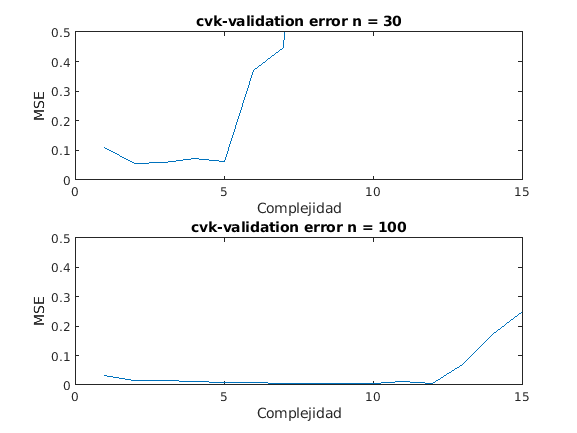

for s=1:length(n_sample)

    for t=1:n_experiments
        
        index = randperm(1000, n_sample(s));
        xsample = x(index);
        ysample = y(index);
        
        if t == 1
            c = cvpartition(n_sample(s),'KFold',10);
            cnew = c;
        end
    
        for i=1:max_complex
            fun = @(xTrain,yTrain,xTest,yTest)(mse(yTest - polyval(polyfit(xTrain, yTrain, i), xTest))); 
            cv_error(t, i) = sum(crossval(fun,xsample',ysample' ,'partition',cnew))/sum(cnew.TestSize);
        end
        
        cnew = repartition(c);    
        [~ , best_model] = min(cv_error(t, :));
        best_local_model_cv(s, t) = best_model;
    end
    
    subplot(2,1,s);
    plot(1:max_complex, mean(cv_error))
    xlim([0, 15])
    ylim([0, 0.5])
    title(['cvk-validation error n = ',num2str(n_sample(s))])
    xlabel('Complejidad') 
    ylabel('MSE') 

end

## Bootstrap

Para bootstrap utilizaremos 100 muestras de bootstrap del mismo tamaño que para los demás experimentos. Esto es debido a que nuestro es objetivo es comparar los resultados entre los distintos métodos así que tenemos que equiparar el tamaño de las muestras para que sean equiparables los conjuntos de entrenamiento y validación de todos los métodos, tanto de remuestreo como de penalización. El tamañao de la muestra para validar será del 50% la de entrenamiento, esto viene dado debido a que las muestras tienen mucha varianza con respecto al tamaño de los datos, y esto hace que el ajuste a funciones aproximadoras polinómicas sea muy variable en cuanto el error, así que usaremos un tamaño de muestra para la validación algo más grande que el 30% estándar.

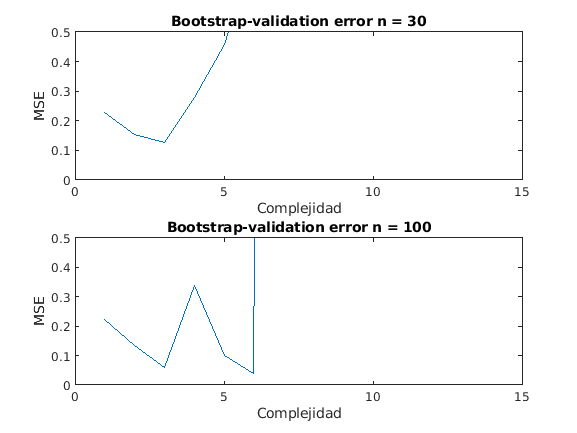


for s=1:length(n_sample)
    index = randperm(1000, (n_sample(s) + n_sample(s) * 0.5));

    for t=1:n_experiments
        
        xsample = x(index);
        ysample = y(index);
        
        size_boostrap_sample = 30;
        n_bootstrap_samples = 25;
          
        [~, train_index] = bootstrp(1, @mean, xsample(1:size_boostrap_sample));
        xTrain = xsample(train_index);
        yTrain = ysample(train_index);
        
        aux=1;
        for i=i:length(train_index)
           if find(i==train_index)
              xtest(aux)=xsample(i); 
              ytest(aux)=ysample(i);
              aux=aux+1;
           end
        end
            
        for i=1:max_complex
            model = polyfit(xTrain, yTrain, i);
            bootstrap_error(t, i) = mse(ytest, polyval(model, xtest));
        end 
        
        [~ , best_model] = min(bootstrap_error(t, :));
        best_local_model_bt(s, t) = best_model;
    end
    
    subplot(2,1,s);
    plot(1:max_complex, mean(bootstrap_error))
    xlim([0, 15])
    ylim([0, 0.5])
    title(['Bootstrap-validation error n = ', num2str(n_sample(s))])
    xlabel('Complejidad') 
    ylabel('MSE') 

end

## Comparativa del error y la distribución de la complejidad haciendo uso de métodos de remuestreo

Con respecto al error podemos ver que el método *kcrossvalidation* tiende a disminuir conforme crece el tamaño de la muestra, en primera instancia mientras bootstrap se mantiene más estable.

Con respecto a la distribución de la complejidad, podemos over como *kcrossvalidation* aunque en un principio tiende a coger modelos menores que *Boostrap* luego escoge modelos mayores que esté y bastante mayores con respecto a sí mismo. Por el contrario boostrap se mantiene con una baja variabilidad y teniendo siempre una cola mayor hacia modelos con menor complejidad.

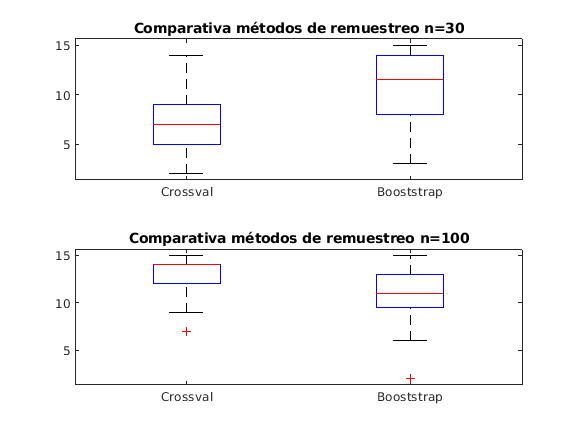


for s=1:length(n_sample)
    subplot(2,1,s)
    boxplot([best_local_model_cv(s,:)', best_local_model_bt(s,:)'],{'Crossval','Booststrap'})
    title(['Comparativa métodos de remuestreo n=',num2str(n_sample(s))])
end

## Métodos de penalización

Los métodos de penalización elegidos serán *AICc* y *AIC.*

## AICC y AIC

Hemos elegido estos métodos debido la forma en que penalizan observada. Mientras que el método *AICC* muestra una alta penalización con muestras pequeñas,  el método *AIC* presenta una menor penalización situándose por debajo de *AICC* gracias a esta elección podremos ver las dos caras de la moneda en cuanto a penalización en la elección de los modelos (mayor penalización vs menor penalización) y observar que cuando la muestra aumenta es indiferente la elección entre ambos.

Las condiciones iniciales (tamaño de muestra, complejidad... etc) serán identícas a la de los otros experimentos.

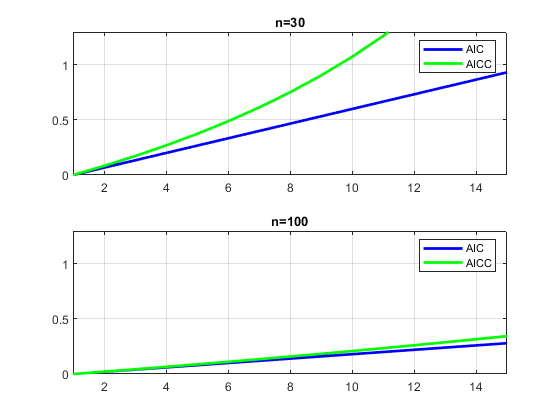

 
k=1:max_complex;
for s=1:length(n_sample)
    AIC=2*(k+1)./n;
    AICC=(n+k)./(n-k-2);
    
    AIC=AIC-AIC(1);
    AICC=AICC-AICC(1);
    
    subplot(2,1,s);
    plot(k,AIC,'-b','LineWidth',2),hold on;
    plot(k,AICC,'-g','LineWidth',2),hold off;
    legend('AIC','AICC'),grid;
    axis([1,15,0,1.3])
    title(['Tamaño de muestra n=',num2str(n_sample(s))])

end

## AIC

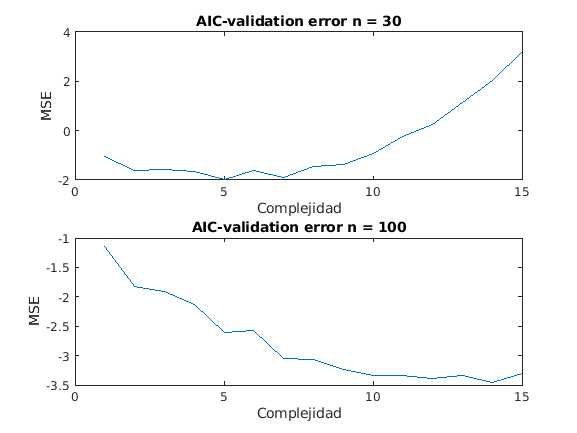

k=1:max_complex;

for s=1:length(n_sample)

    AIC=2*(k+1)./n_sample(s);
    
    for t=1:n_experiments
        index = randperm(1000, n_sample(s));   
        xtrain = x(index);
        ytrain = y(index);
        
        index = randperm(1000, n_sample(s));   
        xtest = x(index);
        ytest = y(index);
        
        for i=1:max_complex
            model = polyfit(xtrain, ytrain, i);
            e_error(t, i) = mse(ytest, polyval(model, xtest));
        end
        
        aic_error(t, :) = log(e_error(t, :)) + AIC;
        
       [~ , best_model] = min(aic_error(t, :));
       best_local_model_aic(s, t) = best_model;
    end
    
    subplot(2,1, s)
    plot(1:max_complex, mean(aic_error))
    xlim([0, 15])
    title(['AIC-validation error n = ', num2str(n_sample(s))])
    xlabel('Complejidad') 
    ylabel('MSE') 
    
end

## AICc

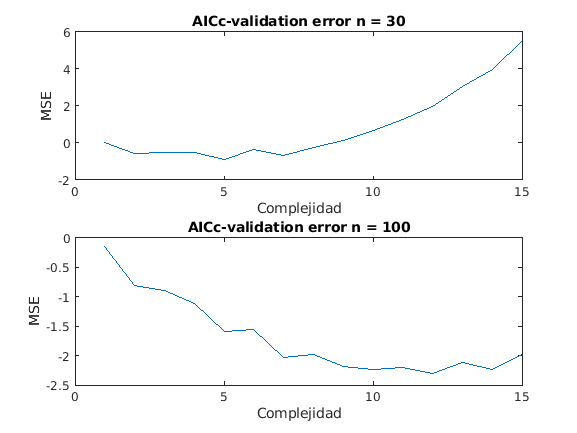

k=1:max_complex;

for s=1:length(n_sample)
    
    AICC=(n_sample(s)+k)./(n_sample(s)-k-2);
    
    for t=1:n_experiments
        index = randperm(1000, n_sample(s));   
        xtrain = x(index);
        ytrain = y(index);
        
        index = randperm(1000, n_sample(s));   
        xtest = x(index);
        ytest = y(index);
        
        for i=1:max_complex
            model = polyfit(xtrain, ytrain, i);
            e_error(t, i) = mse(ytest, polyval(model, xtest));
        end
        
        aicc_error(t, :) = log(e_error(t, :)) + AICC;
        
       [~ , best_model] = min(aicc_error(t, :));
       best_local_model_aicc(s, t) = best_model;
    end
    
    subplot(2,1, s)
    plot(1:max_complex, mean(aicc_error))
    xlim([0, 15])
    title(['AICc-validation error n = ', num2str(n_sample(s))])
    xlabel('Complejidad') 
    ylabel('MSE') 
end

## Comparativa del error la distribución de la complejidad haciendo uso de métodos de  penalización

Con repespecto al error podemos ver el comportamiendo esperado, aunque son similares, podemos ver como el *AICC* penaliza mayormente al error obsevandose una curva más plana y mayor error.

Con respecto a la distribución de los modelos seleccionados podemos observar la misma tendencia debido aque el método *AICC* penaliza de una form más alta, los modelos seleccionados son menores que los seleccionados por el método *AIC.*

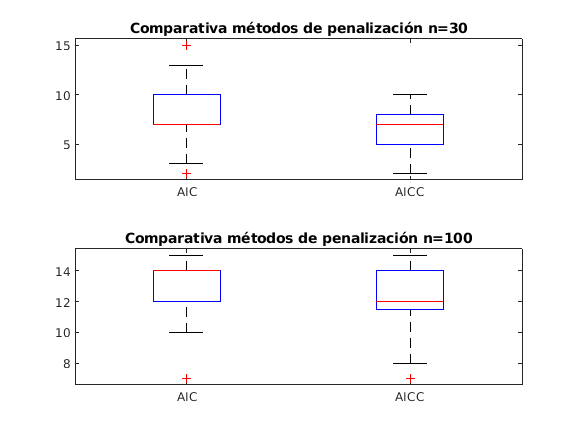


for s=1:length(n_sample)
    subplot(2,1,s)
    boxplot([best_local_model_aic(s,:)', best_local_model_aicc(s,:)'],{'AIC','AICC'})
    title(['Comparativa métodos de penalización n=',num2str(n_sample(s))])
end

## Comparativa de la distribución de la complejidad entre modelos de validación y penalización

Como podemos ver los resultados son bastante estandarares, reflejando los resultados teóricos. *kcrossvalidation* aunque estable, tendiendo a obtener modelos de mayor complejidad, boostrap tendiendo a obtener modelos de menor complejidad pero con una baja variabilidad, y los métodos de penalización con un comportamiendo similar pero cambiando su media debido a sus diferencias en penalización y que al final, al aumentar la muestra acaban convergiendo.

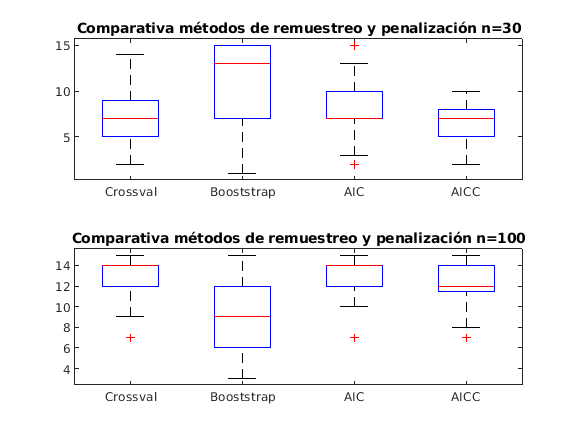

for s=1:length(n_sample) 
    subplot(2,1,s)
    boxplot([best_local_model_cv(s,:)', best_local_model_bt(s,:)',best_local_model_aic(s,:)',best_local_model_aicc(s,:)'],{'Crossval','Booststrap','AIC','AICC'})
    title(['Comparativa métodos de remuestreo y penalización n=',num2str(n_sample(s))])
end